## **Question 1**

**1.1)**

- Implement the Lorenz-96 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Importing Lorenz96 model
m = otp.lorenz96.presets.Canonical;

% Model configurations
n_states = 40;
x0 = normrnd(0,sqrt(16),[n_states,1]); % Inital condition of y0 drawn from N(0,16)
dt = 0.1; % time unit

% Solving for for 5 time units (0.5) using inital conditions above
[~, x_true] = ode45(m.RHS.F, [0 dt*5], x0); % This is x[-1]true/reference state. TODO - better naming convention/store in array
x_true = x_true(end,:).'; % Extracting states at final timestep

**1.2)**

- Compute Nens normal random perturbations εbi ∼ N (0, σ2 INstate ) with σ = 0.2.

- Add to x[-1]true, and integrate the system starting from the perturbed initial conditions for ∆t time units.

- Save the resulting Nens states x. The members of this ensemble represent our set of background states Xb[0] .

n_ens = 100;
sigma = 0.2;

% create ensemble members from perturbations of x_true
eps = normrnd(0,sigma,[n_states,n_ens]); % Perturbations
x_perturbed = x_true + eps;  % Adding to x_true[-1]

% init storage for ensemble (background state)
X_ens = zeros(n_states, n_ens);

% intergate system for one time unit for each ensemble member, store result
for i = 1:n_ens
    [~, x_ens] = ode45(m.RHS.F, [0.5 0.6], x_perturbed(:, i));
    X_ens(:, i) = x_ens(end, :);
end

**1.3)**

- Using a large number of ensemble members compute the ensemble covariance Pb0.

- Check its condition number. If it is large build a modified background covariance that leads to a reasonably small condition number of the resulting covariance.

- This is our B0.

% A problem is called well-conditioned, if its condition number is small, i.e., in the order of 10, 100 or 1000
% and ill-conditioned if it is large: in the order of 10^6 - 10^10, and larger.
% https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/Webpages/lehre/na_08/Lab1/5_CondStab/html/CondStab.html

B0 = cov(X_ens.');
cond(B0)

ans = 84.8676

X_ens_mean = mean(X_ens, 2);
X_delta = X_ens - X_ens_mean;
B0_a = (1/(n_ens-1)).*(X_delta*X_delta.');

cond(B0_a)

ans = 84.8676

alpha = 0.01;
B0_b = (1-alpha)*B0 + alpha*eye(n_states);
cond(B0_b)

ans = 15.7584

**1.4) **

- Obtain x0b by selecting one state with the smallest deviation from xtrue

[M,I] = min(sum(abs(X_ens - x_true(end,:).')));
x0b = X_ens(:, I);

**1.5)**

- Run the reference trajectory starting from x_true[0] over the interval [0, T].

- Save the solution every ∆t time units.

- At each ti = i ∆t generate N_ens synthetic observations by adding to the reference solution H*xi normal random noise drawn from N (0, R), R = r^2 I N_obs, with r = 0.025.

T = 10;
t = 0.6;
time_steps = 0.6:dt:T;
x_start = x_true;
X_ref = zeros(n_states, length(time_steps));
X_ref(:, 1) = x_start;

% Run forward model and save results
for t_id = 1:(length(time_steps)-1)
    
    [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], x_start);
    X_ref(:, t_id+1) = x(end,:);
    x_start = x(end,:).'; % For next iterations, use starting conditions based on final state of forward model

end

% Apply observation operator and add random noise to reference trajectory

% Generating observation operator (every second state)
A = eye(20);
M = 1;
k = 1;
N = size(A);
H = reshape([reshape(A,M,[]);zeros(k,N(1)/M*N(2))],[],N(2)).';

% Applying observation vector to reference trajectory
% Clone observations -> ensemble 
X_obvs = H * X_ref;
X_obvs_ens = repmat(X_obvs, 1,1, n_ens);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025;
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));
X_obvs_ens = X_obvs_ens + obvs_noise;

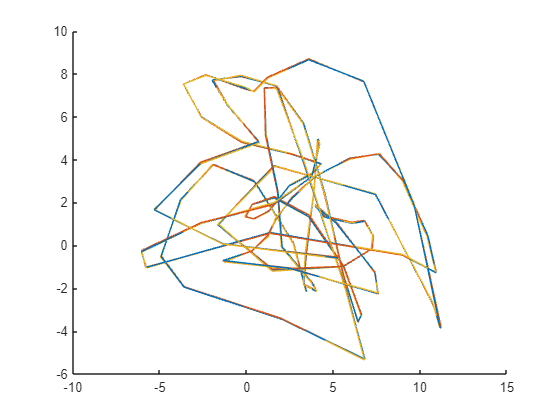


% Plotting sample reference and perturbed states (for 2 ensemble members)
clf
hold on
plot3(X_ref(1, :), X_ref(3, :), X_ref(5, :));
plot3(X_obvs_ens(1, :, 1), X_obvs_ens(2, :, 1), X_obvs_ens(3, :, 1));
plot3(X_obvs_ens(1, :, 2), X_obvs_ens(2, :, 2), X_obvs_ens(3, :, 2));

## **Question 2**

**2.1)**

- Consider the data assimilation problem posed over the interval [0, T], starting with initial background states from N (xb[0] , B0).

- Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from above.

x0b;
B0;
X_t = mvnrnd(x0b,B0,n_ens).'; % TODO - Unclear if these need to be resampled from this distribution or use the ones from above?

% TODO - are we ment to do this for every timestep in the above
% observation? such that the ensemble size can be altered arbitarily? This
% feels like a repetition - however would also get the covariance B_n for
% every step - this should roughly be the same however as the noise is
% constant for all timesteps??

% For now - lets just use the existing ensmble and see how it works

% X_obvs_ens: ensemble of observations for every timestep
% From this can calculate the covar etc




**2.2)**

- Solve the data assimilation problem using the standard (perturbed observations) version of EnKF.

- You will need to implement the filter, run it, and assess the quality of the results.

% TBD

R = 0.025.^2 * eye(20);% Define this above (observation errors)
X_ens_a = mvnrnd(x0b,B0,n_ens).'; % TODO - Unclear if these need to be resampled from this distribution or use the ones from above?

X_ens_array = zeros(n_states, n_ens, length(time_steps));
X_ens_array(:,:,1) = X_ens_a;
B = cov(X_ens_a.');


for t_id = 1:(length(time_steps)-1)
    
    B = cov(X_ens_a.');
    %cond(B)

    K_t = B * H.' * inv(H * B * H.' + R);  % Kalman gain
    Y_t = squeeze(X_obvs_ens(:,t_id,:)); % Get observations from prior trajectory with observation errors added
    X_ens_a = X_ens_a + K_t * (Y_t - H * X_ens_a);   % Caclulate innovation factor and update 
    
    % Move forward in time via model
    for i = 1:n_ens
        [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], X_ens_a(:, i));
        X_ens_a(:, i) = x(end, :).';
        X_ens_array(:,i,t_id+1) = X_ens_a(:, i);
    end
    time_steps(t_id)
end

ans = 0.6000

ans = 0.7000

ans = 0.8000

ans = 0.9000

ans = 1

ans = 1.1000

ans = 1.2000

ans = 1.3000

ans = 1.4000

ans = 1.5000

ans = 1.6000

ans = 1.7000

ans = 1.8000

ans = 1.9000

ans = 2

ans = 2.1000

ans = 2.2000

ans = 2.3000

ans = 2.4000

ans = 2.5000

ans = 2.6000

ans = 2.7000

ans = 2.8000

ans = 2.9000

ans = 3.0000

ans = 3.1000

ans = 3.2000

ans = 3.3000

ans = 3.4000

ans = 3.5000

ans = 3.6000

ans = 3.7000

ans = 3.8000

ans = 3.9000

ans = 4

ans = 4.1000

ans = 4.2000

ans = 4.3000

ans = 4.4000

ans = 4.5000

ans = 4.6000

ans = 4.7000

ans = 4.8000

ans = 4.9000

ans = 5

ans = 5.1000

ans = 5.2000

ans = 5.3000

ans = 5.4000

ans = 5.5000

ans = 5.6000

ans = 5.7000

ans = 5.8000

ans = 5.9000

ans = 6

ans = 6.1000

ans = 6.2000

ans = 6.3000

ans = 6.4000

ans = 6.5000

ans = 6.6000

ans = 6.7000

ans = 6.8000

ans = 6.9000

ans = 7

ans = 7.1000

ans = 7.2000

ans = 7.3000

ans = 7.4000

ans = 7.5000

ans = 7.6000

ans = 7.7000

ans = 7.8000

ans = 7.9000

ans = 8

ans = 8.1000

ans = 8.2000

ans = 8.3000

ans = 8.4000

ans = 8.5000

ans = 8.6000

ans = 8.7000

ans = 8.8000

ans = 8.9000

ans = 9

ans = 9.1000

ans = 9.2000

ans = 9.3000

ans = 9.4000

ans = 9.5000

ans = 9.6000

ans = 9.7000

ans = 9.8000

ans = 9.9000


% Plotting sample reference and perturbed states (for 2 ensemble members)
clf
hold on


state_id = 20

state_id = 20

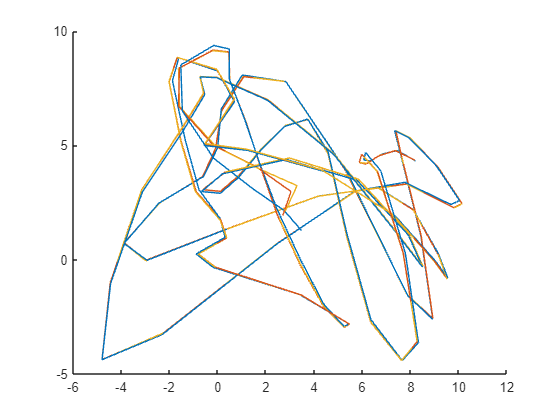

plot3(X_ref(state_id, :), X_ref(state_id+2, :), X_ref(state_id+4, :));
%plot3(X_ens_array(1, 1, :), X_ens_array(2, 1, :), X_ens_array(3, 1, :));
plot3(squeeze(X_ens_array(state_id, 1, :)), squeeze(X_ens_array(state_id+2, 1, :)),squeeze(X_ens_array(state_id+4, 1, :)))
plot3(squeeze(X_ens_array(state_id, 2, :)), squeeze(X_ens_array(state_id+2, 2, :)),squeeze(X_ens_array(state_id+4, 2, :)))

% Calculating accuracy of the ensemble

X_ens_mean = squeeze(mean(X_ens_array, 2))

X_ens_mean =    -1.2431   -0.3011   -5.0649   -2.6814    0.7019   -1.0654   -2.0983   -0.5883    1.5979    3.1979    4.4021    5.4764    6.3611    6.6395    5.7716    3.8884    1.8606    0.4784    0.0144    0.4085    1.2474    1.8169    2.3816    3.6693    4.1524    2.5453   -0.2506   -2.5448   -3.5835   -2.3756   -0.1605    0.3570    1.2024    3.5475    6.6764    9.6051   11.1658   10.7433    7.4246    1.4998   -1.6865    1.4738    5.6131    7.2403    7.3136    7.0076    6.8258    6.0142    4.4333    3.9335
   -0.0333    0.3595    2.2772    1.3705    1.4053    2.1466    0.9723    0.6989    1.8708    3.6194    5.0916    5.0274    2.8686   -0.4039   -3.0384   -3.9439   -3.5743   -2.7066   -1.7147   -0.8378   -0.2830   -0.0042    0.1313    0.1555    0.1618    0.3066    0.8494    1.6081    1.3769   -0.3939   -0.8200    0.2098    1.3941    3.1507    5.7995    7.4228    3.4990   -3.0311   -5.9285   -5.4414   -4.1682   -3.0251   -0.9994    1.4703    3.5021    4.9742    6.1485    7.5510    9.

clf
hold on
state_id = 15

state_id = 15

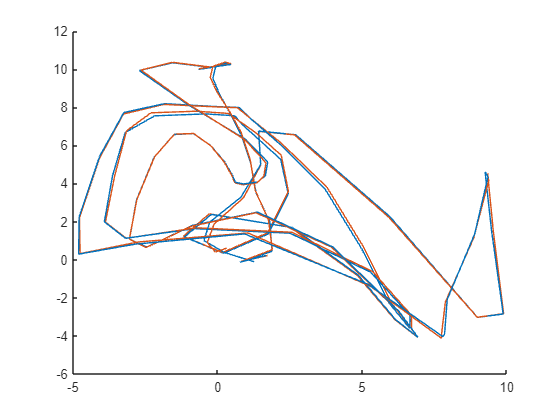

plot3(X_ref(state_id, :), X_ref(state_id+2, :), X_ref(state_id+4, :));
plot3(X_ens_mean(state_id, :), X_ens_mean(state_id+2, :), X_ens_mean(state_id+4, :));

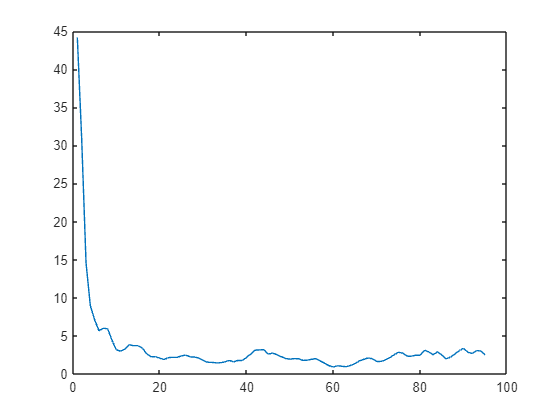

norm_1 = vecnorm(X_ref-X_ens_mean, 1, 1);
norm_2 = vecnorm(X_ref-X_ens_mean, 2, 1);
norm_inf = vecnorm(X_ref-X_ens_mean, Inf, 1);
clf
plot(norm_1)

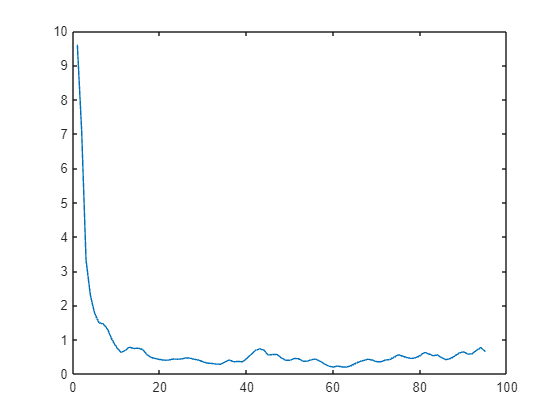

plot(norm_2)

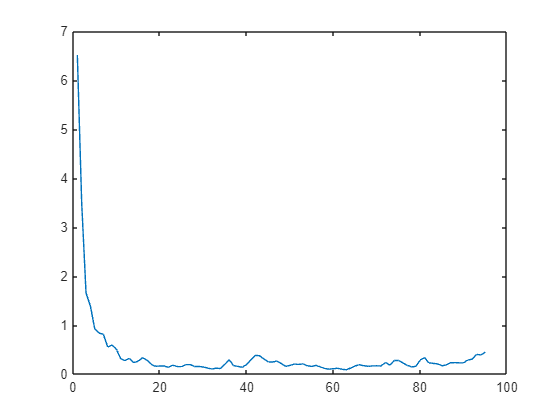

plot(norm_inf)

**2.3)**

- Solve the data assimilation problem using a square root filter (EnSRF), e.g., ETKF.

- You will need to implement the filter, run it, and assess the quality of the results.

% TBD

**2.4)**

For each case plot: 

- The time evolution of the error in the analysis ensemble mean, compared to the reference trajectory.

- The rank histogram for one of the observations.

% TBD

**2.5)**

- Apply covariance localization. Use a Gaspari-Cohn function with a decorrelation parameter L = 5.

- Repeat the EnKF and ETKF numerical experiments and compare the results against the analysis obtained without localization.

% TBD

**2.6)**

- In addition to localization, apply multiplicative covariance inflation with a parameter α = 1.02.

-  Again, repeat the EnKF and ETKF numerical experiments, and compare the results against the analysis obtained before. 

% TBD